# 1). 2p imaging processing pipeline

## 1. Set the global variable strDir_CaRMA_Wiki

*Please change the strDir_CaRMA_Wiki variable to your own path of CaRMA Wiki in initDir_CaRMA_Wiki.m file*

initDir_CaRMA_Wiki()
% change # strDir_CaRMA_Wiki = 'Z:\Zhenggang\CaRMApipeline';

## 2. Split the volumetric images recorded by Scanimage into images of individual imaging planes. Details are in Batch_SplitImages_SI_FastZ.m.

- Batch_SplitImages_SI_FastZ.m processes the ScanImage files in a batch.

- For each image file, the script creates a subfolder containing all splitted images of individual imaging plane. The splitted images are used for image registration to correct the image motion. Please keep the subfolder organization for further processing.

- The script generates an average intensity projection image for each imaging plane, whose name is ended with "_Avg.tif". These average images are used as the first round of image template in image registration. 

- To make it easy to examine the images in FiJi, the script finally combines the splitted images into a big file so that all imaging planes can be exmamined simultaneously in FiJi.

- The script also saved the meta information of each image to a .mat file.

**    Note1 :  The script uses modified (fix some bugs) opentif function from ScanImage 2016b (**[Vidrio Technologies](http://scanimage.vidriotechnologies.com/display/SI2016/Open+Tiff)**) to read ScanImage files. It needs their permission for redistribution. **

**    Note2: After submitting our manuscripts, I found opentif function became quite slow in Matlab 2019 and later, because setDirectory function becomes quite slow in those versions of Matlab. Thus, I further modified the opentif function to make it faster. In additon, I wrote openSITif interface function to use ScanImageTiffReader (**[https://vidriotech.gitlab.io/scanimagetiffreader-matlab/](https://vidriotech.gitlab.io/scanimagetiffreader-matlab/)**) to read the ScanImage image data. Because I used the opentif function in my analysis pipeline,the default method in the script is opentif. However, ScanImageTiffReader method is much faster, if you want to use ScanImageTiffReader method, you can change the code on ****line 23**** in SplitImages_SI_FastZ.m (**`[Header,Aout,imgInfo] = openSITif(strFn); -> [Header,Aout,imgInfo] = openSITif(strFn, false);`**)**

**Note3 from Zhenggang:  The script uses opentif or openSITif function, which all need the Scanimage image data. If your data has been processed, it may loss the image information and you can not open tif. Need other scripts to open. **imread ('DEM_30s.tif', 'tif'); or read(r)

% Batch_SplitImages_SI_FastZ only use for one day 

% one way I did is that I list % the directory containing ScanImage
% files to be splitted as different strDir

Batch_SplitImages_SI_FastZ_ZZG

Processing file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00001.tif


Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00001_S\492241_ghrelin_00001_S1_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00001_S\492241_ghrelin_00001_S1_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00001_S\492241_ghrelin_00001_S2_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00001_S\492241_ghrelin_00001_S2_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00001_S\492241_ghrelin_00001_S3_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00001_S\492241_ghrelin_00001_S3_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMAp

Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00002_S\492241_ghrelin_00002_S1_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00002_S\492241_ghrelin_00002_S1_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00002_S\492241_ghrelin_00002_S2_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00002_S\492241_ghrelin_00002_S2_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00002_S\492241_ghrelin_00002_S3_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00002_S\492241_ghrelin_00002_S3_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMAp

Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00003_S\492241_ghrelin_00003_S1_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00003_S\492241_ghrelin_00003_S1_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00003_S\492241_ghrelin_00003_S2_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00003_S\492241_ghrelin_00003_S2_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00003_S\492241_ghrelin_00003_S3_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00003_S\492241_ghrelin_00003_S3_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMAp

Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00004_S\492241_ghrelin_00004_S1_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00004_S\492241_ghrelin_00004_S1_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00004_S\492241_ghrelin_00004_S2_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00004_S\492241_ghrelin_00004_S2_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00004_S\492241_ghrelin_00004_S3_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00004_S\492241_ghrelin_00004_S3_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMAp

Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00005_S\492241_ghrelin_00005_S1_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00005_S\492241_ghrelin_00005_S1_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00005_S\492241_ghrelin_00005_S2_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00005_S\492241_ghrelin_00005_S2_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00005_S\492241_ghrelin_00005_S3_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00005_S\492241_ghrelin_00005_S3_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMAp

Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00006_S\492241_ghrelin_00006_S1_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00006_S\492241_ghrelin_00006_S1_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00006_S\492241_ghrelin_00006_S2_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00006_S\492241_ghrelin_00006_S2_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00006_S\492241_ghrelin_00006_S3_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00006_S\492241_ghrelin_00006_S3_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMAp

Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00007_S\492241_ghrelin_00007_S1_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00007_S\492241_ghrelin_00007_S1_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00007_S\492241_ghrelin_00007_S2_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00007_S\492241_ghrelin_00007_S2_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00007_S\492241_ghrelin_00007_S3_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00007_S\492241_ghrelin_00007_S3_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMAp

Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00008_S\492241_ghrelin_00008_S1_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00008_S\492241_ghrelin_00008_S1_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00008_S\492241_ghrelin_00008_S2_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00008_S\492241_ghrelin_00008_S2_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00008_S\492241_ghrelin_00008_S3_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00008_S\492241_ghrelin_00008_S3_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMAp

Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00009_S\492241_ghrelin_00009_S1_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00009_S\492241_ghrelin_00009_S1_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00009_S\492241_ghrelin_00009_S2_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00009_S\492241_ghrelin_00009_S2_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00009_S\492241_ghrelin_00009_S3_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00009_S\492241_ghrelin_00009_S3_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMAp

Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00010_S\492241_ghrelin_00010_S1_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00010_S\492241_ghrelin_00010_S1_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00010_S\492241_ghrelin_00010_S2_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00010_S\492241_ghrelin_00010_S2_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00010_S\492241_ghrelin_00010_S3_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00010_S\492241_ghrelin_00010_S3_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMAp

Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00011_S\492241_ghrelin_00011_S1_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00011_S\492241_ghrelin_00011_S1_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00011_S\492241_ghrelin_00011_S2_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00011_S\492241_ghrelin_00011_S2_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00011_S\492241_ghrelin_00011_S3_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00011_S\492241_ghrelin_00011_S3_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMAp

Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00012_S\492241_ghrelin_00012_S1_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00012_S\492241_ghrelin_00012_S1_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00012_S\492241_ghrelin_00012_S2_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00012_S\492241_ghrelin_00012_S2_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00012_S\492241_ghrelin_00012_S3_C1.tif
Writting file: Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM492241_ghrelin_day4\492241_ghrelin_00012_S\492241_ghrelin_00012_S3_C1_Avg.tif
Writting file: Z:\Zhenggang\CaRMAp

% The other way is batch processing
% Under the script is Batch_SplitImages_SI_FastZ_1

For the example data, the following gray subfolders and files are generated by the script.

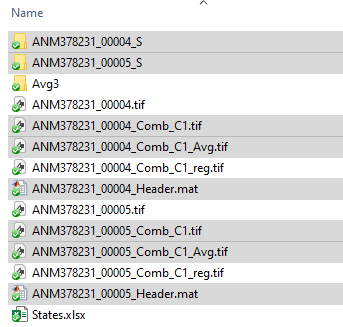 

The splitted files in ANM378231_00004_S are shown below.

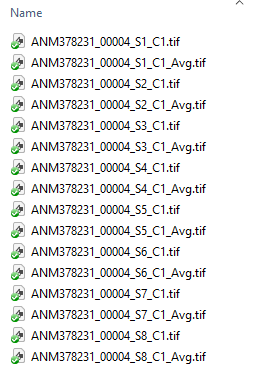

## 3. Register the splitted images in each imaging planes across time to correct the motion artifacts. 

- To speed up the process, the script was run in **Janelia Computer Cluster** in parallel.** Please adapt the codes to your own computing environment**. The script also uses Matlab **Parallel Computing Toolbox** to accelerate the computation. If you don't have **Parallel Computing Toolbox**, please change **parfor **to** for** in the script.

- The script registers images acquired from one animal on one day in batch process mode.

- The registration is restricted within one imaging plane.

- To batch process images acquired from multiple animal or on different days, please change the parameters (`clImgDirs, clTrials_GenRefGrp, clTrial_Refs, clTrials_UseRefGrp`) in the second cell. Details about these parameters are in MatlabCmd_2p_FastZ_Vol_Day_par.m

- The script first registers the images acquired in the trials assigned by `clTrials_GenRefGrp` and iterately generates sharp reference images that can be used to register the images acquired in other trials. Then, it registers images from other trials to the reference images assigned by `clTrial_Refs.`

    **Note: Because the script uses Linux shell script to perform the registration, to avoid unexpected error, ****do not include space in the name of your folders****.**

MatlabCmd_2p_FastZ_Vol_Day_par

Error using FindFiles_RegExp (line 29)
No directory found.

Error in MatlabCmd_2p_FastZ_Vol_Day_par (line 43)
    clImgFns = FindFiles_RegExp(strImgFn_Exp, strImgDir_P, true,2)';


%% function
% a. ImgFileReg_2p_par 
% idx_Ref: int, the index of the frame in the Tiff Stack used as reference image. 
% idx_Ref == 0, use the average intensity projection of the tiff stack as the reference image.
% for computing the registration of the reference images
% all ref images will be aligned together???
% bClusterOE: bool, log (true) the output and error from computer cluster
% b.ImgFileReg_2p_par_useRef
%  register other images to the assigned reference images

%% setting
% dir_1='/groups/sternson/sternsonlab/Zhenggang/CaRMApipeline/Example_Data/ANM378231/Fear_Imaging_Exp/ANM496191/';
% clImgDirs = {[dir_1 ,'1211'],[dir_1 ,'1212'],[dir_1,'1213']};
% clTrials_GenRefGrp = {[5],[5],[9]}; 
% clTrial_Refs = {[5],[5],[9]};
% clTrials_UseRefGrp = {[1 2 3 4 5 6 7 8 9 10],[1 2 3 4 5 6 7 8 9 10],[5 6 7 8 9 10 11 12 13 14]};


For the example data with the parameters in above script (using ANM378231_00004.tif as reference),** for each imaging plane**, the following gray files are generated in the subfolder containing the splitted reference images by the script.

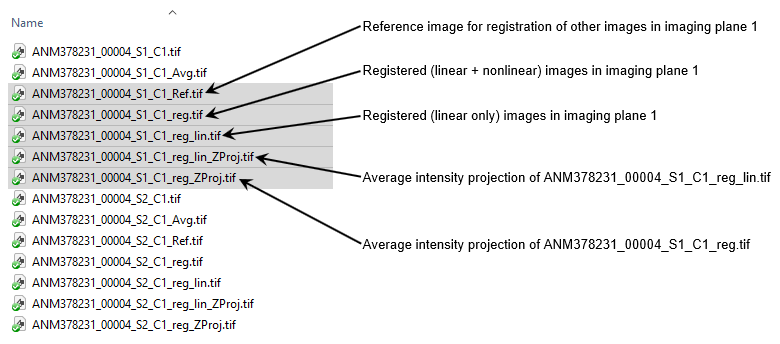

For other images (such as ANM378231_00005.tif in the example data), the script generates following gray files **for each imaging plane**.

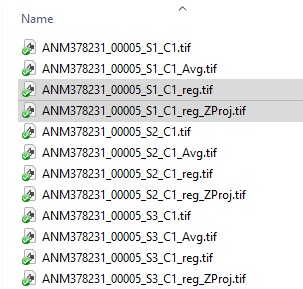

## 4. (*Option*) Combine the registered images of individual imaging planes into a big image file  so that it can be easily examined simultaneously in FiJi.

     Please set the parameters in the second cell. These parameters depend on the starage organization of your data. So, **please organize your data in a consistent storage structure.**

Batch_Comb_RegImgs_From_Sub

%% setting for combining the registered images each day

% %the parent directory containing registered images to be combined
% strImgDir_P = [strDir_CaRMA_Wiki '\Example_Data\ANM378231\Fear_Imaging_Exp\ANM496190_visual_guidence'];
% %regular expression of the file names of subfolders to be combined
% strImgSubDir_RE = '\\1211$';
% 
% %regular expression of the file names
% strANMID = '496190_fastz'; % if name differently, need to check whether the generate filess'name right or not
% strCount = clFnParts{4}; strCh = clFnParts{5};  % check whether the generate file is right or not


%% write Z-stack scale 1 and scale 2
strFn_Avg_Sav = [strDir_Sav filesep strFn '_Avg.tif'];
strFn_Avg_Sav = [strDir_Sav filesep strFn '_Avg_2X.tif'];

%% Behavior videos : neuronal responses to behaviors. 
% Each trial has a video with different frames

For the example data with the parameters in the script above,** for each imaging plane**, the following gray files combining the registered images are generated by the script.

   ** Note1: I left these combined registered images in the example data folder to show registration performance.**

**    Note2: I also put the behavior videos in Fear_Imaging_Exp\Behavior_Video subfolder so that the combined registered images can be further combined with behavior videos to show the neuronal responses to behaviors.**

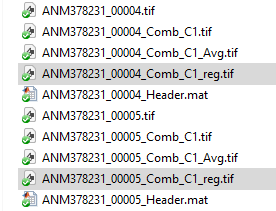

## 5. For each imaging plane, we use FiJi to concatenate the registered images across all trials on one day

- The following script generates a concatenation list as input of the FiJi script in next step.   

CatListGen_2p

% strDir_Img_P = [strDir_CaRMA_Wiki '\Example_Data\ANM378231\Fear_Imaging_Exp\ANM496190_visual_guidence\1212'];
% vtCatTrials = 1:10; % depend on the trails 
% if name differently, need to edit the following script
% strFn_Sav = [C{1} '_' num2str(vtCatTrials(1)) '-' num2str(vtCatTrials(end)) '_' C{4} '_' C{5} '.tif'];
% C{4} C{5} may need to be changed

Examine registraion logs, may not save the right file

The script generates a CatList.log file and a empty subfolder Reg_Cat, as highligted in gray below. Both of them are used in the next step.

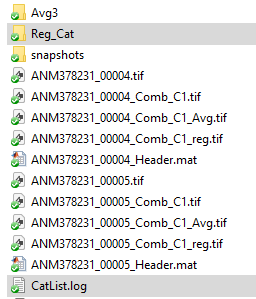

Cat_Exp.ijm % Fiji
% open script in Fiji
% load Cat_Exp.ijm  in Fiji script editor
% load log, and click for each images
% may need 20 min to run images of one day.

        2.  Run** Cat_Exp.ijm** Macro script in FiJi. I did not put these 2 steps in one Matlab script, because (a) the processing is much faster in FiJi; (b) I always check the registration results in FiJi before further analyses. Following shows the concatenated images in Reg_Cat subfoler.

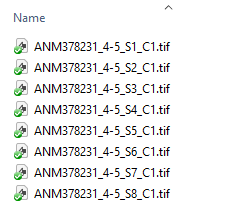

        3. (***Option***) To improve the signal-noise ratio, I temporally downsampled the images by averaging 3 frames into 1 frame. The downsampled images in **Avg3 **subfolder for further analyses are highlighted in gray below.

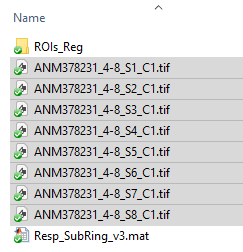

           ** Note1. If you'd like to temporally downsample your images, to avoid averaging across trials, please make sure the total frame number in one trial is divisible by the bin size. For example, 1350/3 = 450 in my case.**

**            Note2. For the downsampled images, I concatenated all images from all trials on that day (trial 4 to 8, but not only trial 4 and 5).**

Average N planes
% I didn't see the avg3 code, but can do it with FIJI
% 1360 planes for 175s, 7.7714 fps
% may need to group every 4 images

## 6. After *ex vivo -> in vivo* registration (details in *ExVivo_InVivo_Reg.mlx*), we can get ROIs for individual identified neurons in ROIs_Reg subfolder as shown below.

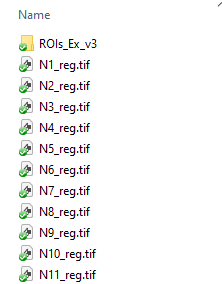

All need done in 256*256 file pixel size

## 7. Extract calcium dynamic responses from images

- Batch_ExtractVolResp_SubRing_v3.m extract calcium signals in batch process mode

- For each neuron, the script generates a exclusive volumetric ROI mask and a volumetric ring-shape background mask in  ROIs_Ex_v3 subfolder

- For each neuron, the script measures its calcium signal by average intensity in ROI mask - average intensity in background mask.

- It saves the extracted calcium signals of all identified neurons in Resp_SubRing_v3.mat file. 

Batch_ExtractVolResp_SubRing_v3
% % compare background mask also.
% clDirs = {
%  [strDir_CaRMA_Wiki '\Example_Data\ANM378231\Fear_Imaging_Exp\ANM496190_visual_guidence\1212\Reg_Cat'];
% };
% %imaging planes.
% strFn_Resp_RE = '_S(\d{1,3}).tif';
% strDir_ROIs = [strDir_VolResp '\ROIs_Reg'];